# Modsim Project 3

## Question

If a penny launcher throws several pennies simulatenously at a piano from a fixed distance, at what angle and speed does each penny need to be thrown in order to play a song on the piano? i.e. such that each penny lands at a different time, in sync with the song?

**Learning Objectives: **As a result of writing this notebook, we (the authors) hope to:

- Increase understanding of optimization

- Increase understanding of physics

- Increase flexibility of code

- Use GitHub effectively

## Methodology

### Schematic Diagram

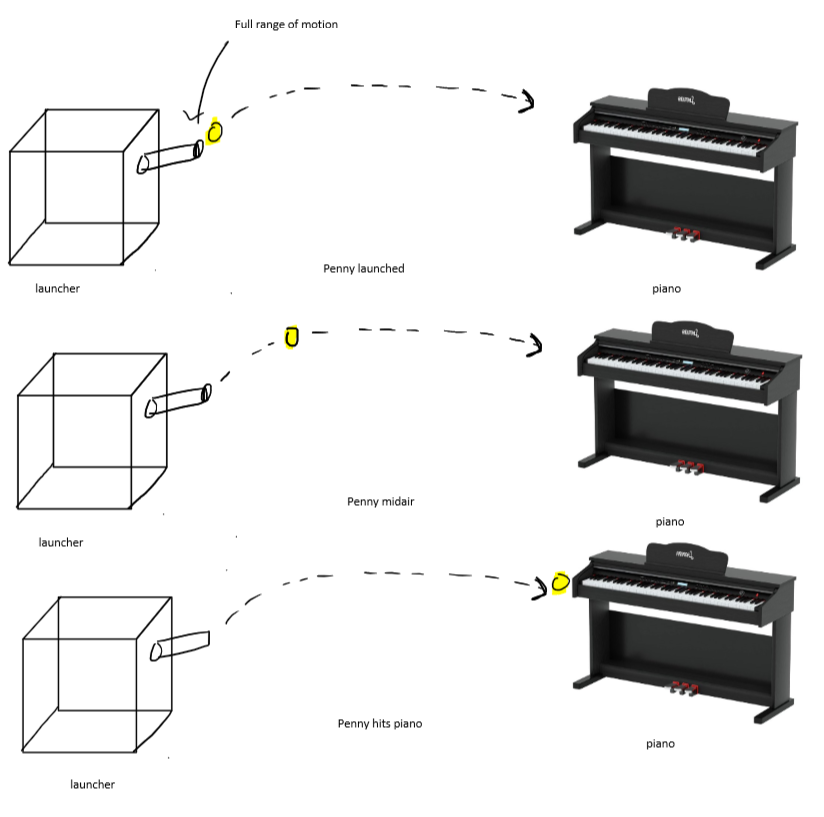

### Free Body Diagram

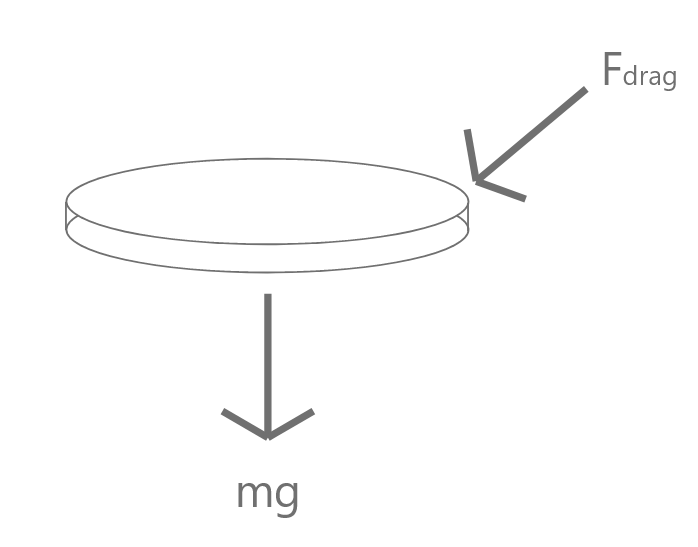

### Stock and Flow

### Mathematical Model

**Parameters**

Penny weight: 2.5g

Penny area affected by drag: $2\ldotp 9{*10}^{-5}$$m^2$

Penny density:$7\ldotp 185{*10}^{-6} m^3$

### Assumptions

- We are assuming that the penny will always be travelling in the direction of a side, so that the face of the penny is never involved in the drag equations.

### Global Variables/Conversions

### **Verification**

## Results

baseball one:

1. stop simulation when it reaches x position of green monster

2. error: calculate difference in end y height - green monster height

3. root finding: find speed at given angle where error = zero

4. fminsearch: find angle which gives the lowest speed

penny:

every angle is going to have a corresponding speed that hits the piano

1. stop simulation when it reaches x position of piano

2. distance error: calculate difference in end x position - piano x position

3. root finding: find speed at given angle where error is 0

4. time error: calculate difference in actual simulation time - desired time

5. fminsearch: find angle/speed pair which both hits the piano and minimizes the difference between simulation time and desired time

calculate approximate angle (no drag) with kinematics

give approximate angle to fminsearch

in function passed to fminsearch:

- use root finding to find speed at given angle where distance error is 0 (and give approximate speed?)

- run ODE simulation

- return time error

of the angle/speed pairs that hit the piano, which ones minimize the difference between simulation time and desired time?

[v0, angle] = get_speed_and_angle(2,1,0)



% angle_range = [0:0.25:90]; % degrees
% count = 1;

% for i=angle_range
%     % convert from degrees to radians
% %     theta = i * (pi/180);
% 
%     % get v0y
%     v0y = v0x * tand(i);
%     angle_and_v0y(count,1) = i;
%     angle_and_v0y(count,2) = v0y;
%     count = count + 1;
% end
% 
% plot(angle_and_v0y(:,1),angle_and_v0y(:,2))

% input: time
% output: angle, speed 

% 
% find angle associated with smallest difference in desired time and actual time


% for each speed and angle, determine if it will give the correct end x position
% at the point where it reaches y position of the piano (end the simulation at that point)

% after 90 degrees, it's not going to hit the piano no matter what
angle_range = [0:0.25:90]; % degrees
% 37.5 is the speed corresponding to 89.5 degrees
speed_range = [0:0.25:40]; % m/s
% there should one angle for each speed at which the pennies are shot
% that hits the piano (reaches the approximate distance of the x position)
count = 1;

for i=speed_range
    for j=angle_range
        % ode_penny parameters: (speed in m/s, angle in degrees)
        [T, M, did_hit_piano,end_time] = ode_penny(i,j);
        % sweep angle and speed; there should be one combination of each angle and
        % speed that will get did_hit_piano
        if did_hit_piano
%             uncomment to debug
%             i, j, end_time
            correct_angle_speed_combos(count, 1) = [i];
            correct_angle_speed_combos(count, 2) = [j];
            correct_angle_speed_combos(count, 3) = [end_time];
            count = count + 1;
        end
    end
end
correct_angle_speed_combos

[T, M, did_hit_piano, end_time] = ode_penny(2.75,30.5);
% sweep angle and speed; there should be one combination of each angle and
% speed that will get did_hit_piano
did_hit_piano
end_time
% X = M(:,1);
% Y = M(:,2);
% plot(X, Y)

## Interpretation

### **Validation**

### **Model Limitations and Future Development**

## Sources